## Classification using perceptron

Provided part of the code. Reading images, extracting color and shape information. Preparing data for training.

A1=imread('apple_04.jpg');
A2=imread('apple_05.jpg');
A3=imread('apple_06.jpg');
A4=imread('apple_07.jpg');
A5=imread('apple_11.jpg');
A6=imread('apple_12.jpg');
A7=imread('apple_13.jpg');
A8=imread('apple_17.jpg');
A9=imread('apple_19.jpg');

P1=imread('pear_01.jpg');
P2=imread('pear_02.jpg');
P3=imread('pear_03.jpg');
P4=imread('pear_09.jpg');

hsv_value_A1=spalva_color(A1); %color
metric_A1=apvalumas_roundness(A1); %roundness

hsv_value_A2=spalva_color(A2); %color
metric_A2=apvalumas_roundness(A2); %roundness

hsv_value_A3=spalva_color(A3); %color
metric_A3=apvalumas_roundness(A3); %roundness

hsv_value_A4=spalva_color(A4); %color
metric_A4=apvalumas_roundness(A4); %roundness

hsv_value_A5=spalva_color(A5); %color
metric_A5=apvalumas_roundness(A5); %roundness

hsv_value_A6=spalva_color(A6); %color
metric_A6=apvalumas_roundness(A6); %roundness

hsv_value_A7=spalva_color(A7); %color
metric_A7=apvalumas_roundness(A7); %roundness

hsv_value_A8=spalva_color(A8); %color
metric_A8=apvalumas_roundness(A8); %roundness

hsv_value_A9=spalva_color(A9); %color
metric_A9=apvalumas_roundness(A9); %roundness

hsv_value_P1=spalva_color(P1); %color
metric_P1=apvalumas_roundness(P1); %roundness

hsv_value_P2=spalva_color(P2); %color
metric_P2=apvalumas_roundness(P2); %roundness

hsv_value_P3=spalva_color(P3); %color
metric_P3=apvalumas_roundness(P3); %roundness

hsv_value_P4=spalva_color(P4); %color
metric_P4=apvalumas_roundness(P4); %roundness

x1=[hsv_value_A1 hsv_value_A2 hsv_value_A3 hsv_value_P1 hsv_value_P2];
x2=[metric_A1 metric_A2 metric_A3 metric_P1 metric_P2];
x1_full=[x1 hsv_value_A4 hsv_value_A5 hsv_value_A6 hsv_value_A7 hsv_value_A8 hsv_value_A9 hsv_value_P3 hsv_value_P4];
x2_full=[x2 metric_A4 metric_A5 metric_A6 metric_A7 metric_A8 metric_A9 metric_P3 metric_P4];

P=[x1;x2];
P_full=[x1_full; x2_full];

T=[1 1 1 0 0];
T_full=[T 1 1 1 1 1 1 0 0];

#### Learning algorithm

w1 = randn(1);
w2 = randn(1);
b = randn(1);

learning_rate = 0.5;
current_example = 1;
while true % executes while the total error is not 0
    v = P(1,current_example) * w1 + P(2,current_example) * w2 + b;

    if v > 0
        y = 1;
    else
        y = 0;
    end
    e_curr = T(current_example) - y;

    w1 = w1 + learning_rate * e_curr * P(1, current_example);
    w2 = w2 + learning_rate * e_curr * P(2, current_example);
    b = b + learning_rate * e_curr;

    v_arr = ((x1 * w1) + (x2 * w2) + b);
    y_arr = zeros(size(v_arr));
    y_arr(v_arr > 0) = 1;
    y_arr(v_arr <= 0) = 0;
    e_arr = T - y_arr;
    % calculate the total error for these 5 inputs
    e = abs(e_arr(1)) + abs(e_arr(2)) + abs(e_arr(3)) + abs(e_arr(4)) + abs(e_arr(5));
    if e == 0
        break
    end
    current_example = current_example + 1;
    if current_example > 5
        current_example = 1;
    end
end

Plotting of generated classification line against input and targets of all available images.

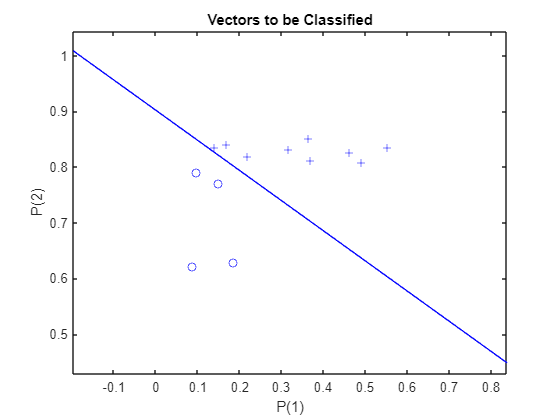

plotpv(P_full,T_full)
plotpc([w1 w2], b)

hsv_apple=[hsv_value_A1 hsv_value_A2 hsv_value_A3 hsv_value_A4 ];
hsv_pear=[hsv_value_P1 hsv_value_P2];
metric_apple=[metric_A1 metric_A2 metric_A3 metric_A4];
metric_pear=[metric_P1 metric_P2];

hsv_apple_stat = [mean(hsv_apple) std(hsv_apple)];
metric_apple_stat = [mean(metric_apple) std(metric_apple)];
hsv_pear_stat = [mean(hsv_pear) std(hsv_pear)];
metric_pear_stat = [mean(metric_pear) std(metric_pear)];
prior_prob_apple = size(hsv_apple) / (size(hsv_apple) + size(hsv_pear));
prior_prob_pear = size(hsv_pear) / (size(hsv_apple) + size(hsv_pear));

full_est_app = log(prior_prob_apple .* normpdf(x1_full, hsv_apple_stat(1), hsv_apple_stat(2)) .* normpdf(x2_full, metric_apple_stat(1), metric_apple_stat(2)));
full_est_pear = log(prior_prob_pear .* normpdf(x1_full, hsv_pear_stat(1), hsv_pear_stat(2)) .* normpdf(x2_full, metric_pear_stat(1), metric_pear_stat(2)));
full_res(full_est_app > full_est_pear) = 1;
full_res(full_est_app <= full_est_pear) = 0;
full_res

full_res =      1     1     1     0     0     1     1     1     1     1     1     0     0


T_full

T_full =      1     1     1     0     0     1     1     1     1     1     1     0     0
